clc;
close all;
clear;

% Define system parameters
C1 = 100; % Heat capacity of room 1 (J/K)
C2 = 100; % Heat capacity of room 2 (J/K)
h = 0.05; % Heat transfer coefficient btw room and outside temp (W/K.m^2)
A_s = 20; % Surface area of room 1 (m^2)
A_s2 = 40; % Surface area of room 2 (m^2)
k = 0.7; % Heat transfer coefficient btw the rooms(W/K.m^2)
Tout = 0; % Outside temperature (degC)
T_desired = [100; 150]; % Desired temperature of each room (degC)

% h = 0;
% k = 0.7; % between room
% A_s = 1;
% A_s2 = 1;

%System State Space Representation
A = [-(h*A_s+k)/C1, k/C1;
    k/C2, -(h*A_s2+k)/C2];
B = [1/C1 0; 0, 1/C2];
C = [1 0; 0 1];
D = 0*eye(2);


% Check if the system is controllable
CO = rank(ctrb(A,B));
if CO < length(A)
    error('The system is not controllable!');
end

% Calculate the observability matrix
O = obsv(A, C);

% Check the rank of the observability matrix
if rank(O) == size(A,1)
    disp('System is observable');
else
    disp('System is not observable');
end

System is observable


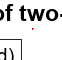


%Define cost function
% Q1 = diag([1,1]);
Q1 = 1e2*diag([1 10]);
Q2 = 2*(C'*C);
R1 = 1*diag([1 1]);
R2 = 100*eye(2);

% LQR controller
[K1,S1,P1] = lqr(A,B,Q1,R1);
[K2,S2,P2] = lqr(A,B,Q2,R2);

% Kalman filter
G = eye(2); % Process noise covariance matrix
Q = 1*eye(2); % Measurement noise covariance matrix
R = 100*eye(2); % Error covariance matrix
[L,P] = lqe(A,G,C,Q,R); % Kalman gain


% Create the state-space model
sys = ss(A, B, C, D);
% Define simulation parameters
tspan = [0 3000]; % Simulation time span (s)
initial_state = [20; 20]; % Initial temperature of each room (degC)
u1 = 100; % Heat input to room 1 (W)
u2 = 150; % Heat input to room 2 (W)

% Define the system dynamics as a function of time and state
f = @(t, S) [(-h*A_s/C1)*(S(1)-Tout) + k/C1*S(2) + u1/C1;
k/C2*S(1) + (-h*A_s2/C2)*(S(2)-Tout) + u2/C2];

% Simulate the uncontrolled system using ODE45 solver
[t1, S] = ode45(f, tspan, initial_state);

% Simulate the LQR-controlled system
sys_cl = ss(A-B*K2, B, C, D);
[y, t, x] = initial(sys_cl, initial_state, tspan);

% Plot the results
figure;
% plot(2,1,1)
plot(t1, S(:,1), 'b-', t1, S(:,2), 'r-');
xlabel('Time (s)');
ylabel('Temperature (degC)');
legend('Room 1 (Uncontrolled)', 'Room 2 (Uncontrolled)', 'Location', 'southeast');
title('Simulation of two-room model');

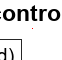


figure;
% plot(2,1,2)
plot(t, x(:,1), 'b-', t, x(:,2), 'r-');
xlabel('Time (s)');
ylabel('Temperature (degC)');
legend('Room 1 (LQR-controlled)', 'Room 2 (LQR-controlled)', 'Location', 'southeast');
title('Simulation of LQR-controlled two-room model');